#### Maciej Górnik

#### gr 1b, 402325

#### EAIiIB, AiR

# **Sterowanie cyfrowe**

## Cel ćwiczenia 

Celem ćwiczenia jest zapoznanie się z budową i działaniem układu regulacji składającego się z ciągłego obiektu regulacji oraz regulatora cyfrowego (dyskretnego). Z taką sytuacją mamy do czynienia w każdej sytuacji, gdy regulator jest zrealizowany na jakiejkolwiek platformie cyfrowej (komputer, sterownik PLC, mikrokontroler, Raspberry Pi, etc). Pomiędzy układami ciągłymi i dyskretnymi występują zarówno analogie, jak i różnice. Podstawowym parametrem układu dyskretnego jest okres próbkowania, określający, jak często odczytywana jest wielkość regulowana z obiektu i wystawiany sygnał sterujący z regulatora na obiekt. Odpowiednikiem transmitancji operatorowej G(s) jest transmitancja dyskretna G(z).

## Przebieg ćwiczeń

W simuliku zamodelowano trzy układy:

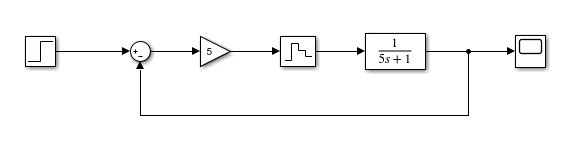

Rys.1. Układ sterowania cyfrowego z regulatorem P i obiektem 1 rzędu

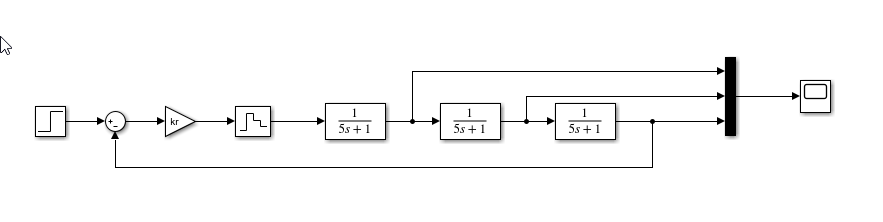

Rys.2. Układ sterowania cyfrowego z regulatorem proporcjonalnym i obiektem wysokiego rzędu.

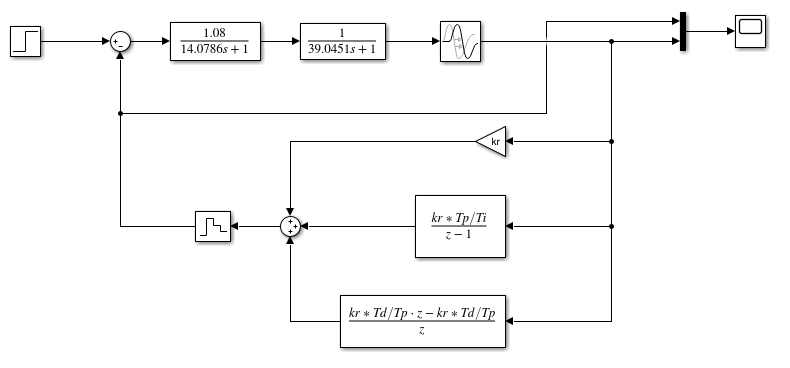

Rys.3. Układ sterowania cyfrowego z regulatorem PID i obiektem z opóźnieniem.

## Ćwiczenie 1

W pierwszej części nalezało zbadać wpływ wartości okresu próbkowania na stabilność układu regulacji cyfrowej. Do danego ćwiczenia zbudowano układ przedstawiony na rysunku 1. Wyniki symulacji zostały przedstawione poniżej.

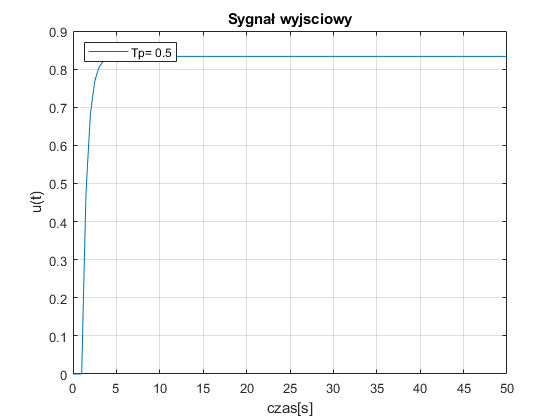

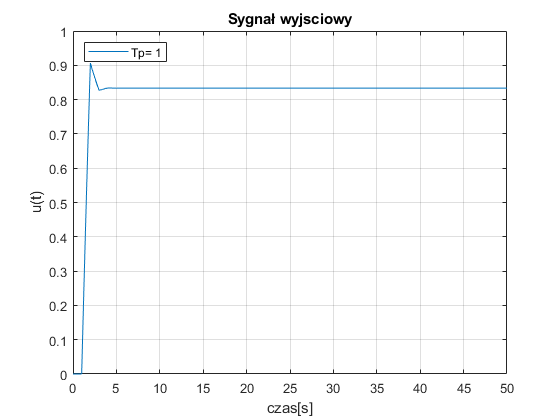

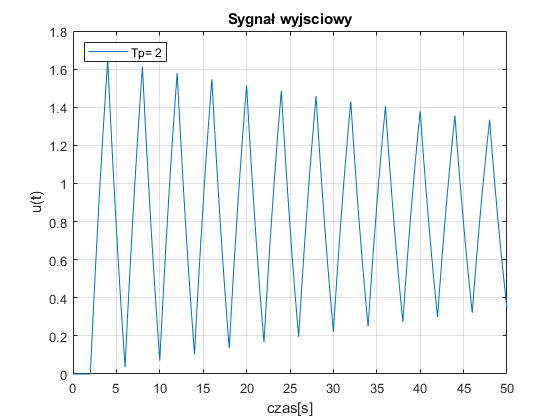

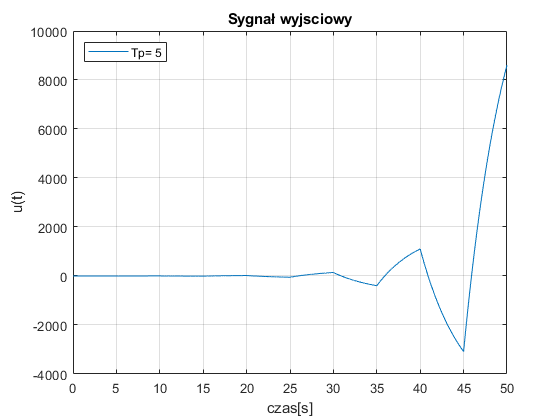

for Tp= [0.5 1 2 5]
    figure;
    out = sim('Zad1.slx');
    u = out.u;
    l = append("Tp= ", string(Tp));
    plot(u.time,u.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    legend("Location","northwest");
    title("Sygnał wyjsciowy")
end

## Ćwiczenie 2

W drugiej części ćwiczenia należało zaobserwować sposób przejścia sygnału cyfrowego przez obiekt wysokiego rzędu. W tym celu należało zbudować model systemu sterowania pokazany na rysunku 2, składający się z dyskretnego regulatora P (proporcjonalnego) z ekstrapolatorem oraz obiektu inercyjnego 3 rzędu, zbudowanego jako szeregowe połączenie trzech elementów 1 rzędu. Wyjście z każdego członu inercyjnego było wyprowadzone na oscyloskop. Wyniki symulacji zostały przedstawione poniżej.

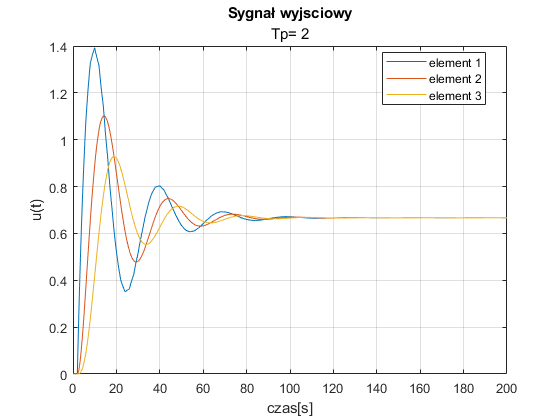

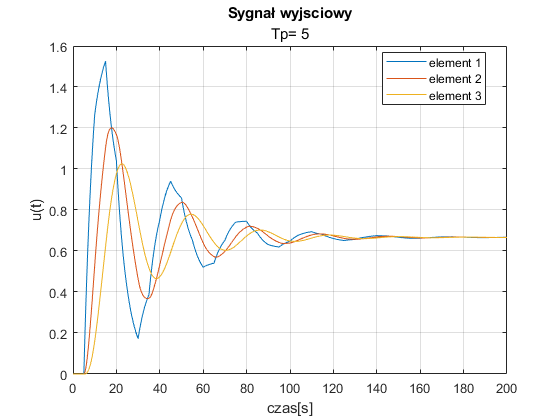

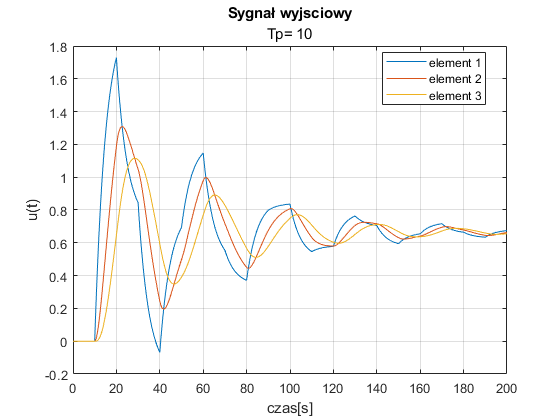

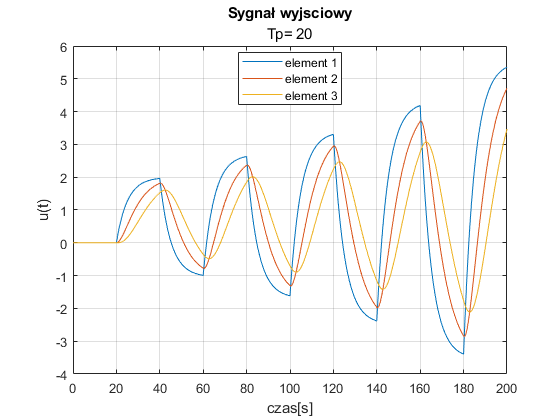

kr = 2;

for Tp= [2 5 10 20]
    figure;
    out = sim('Zad2.slx');
    u = out.u;
    l = append("Tp= ", string(Tp));
    plot(u.time,u.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    legend("element 1","element 2","element 3","Location","best");
    title("Sygnał wyjsciowy", l)
end

## Ćwiczenie 3

W trzeciej części ćwiczenia należało zbadać działanie zamkniętego układu regulacji cyfrowej z dyskretnym regulatorem PID. W tym celu należało zbudować model systemu sterowania pokazany na rysunku 3.

Obiektem regulacji był obiekt o transmitancji:

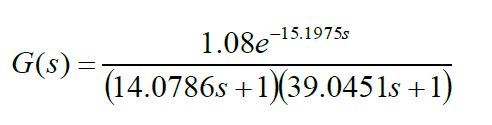

Dyskretny (cyfrowy) regulator PID był opisany następującą transmitancją dyskretną:

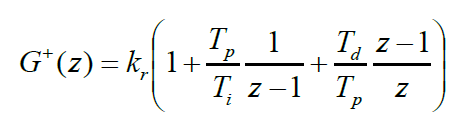

Wyniki symulacji zostały przedstawione poniżej.

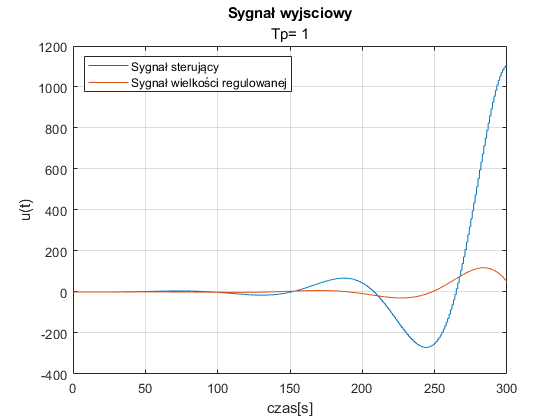

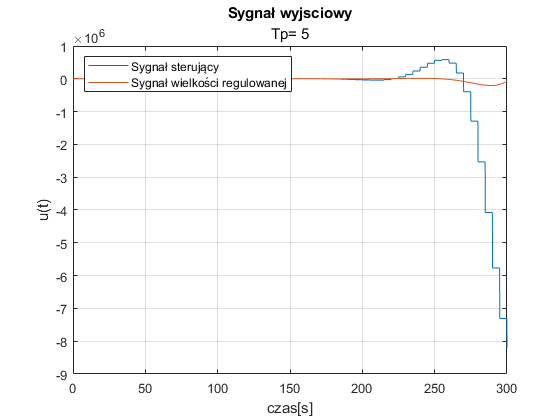

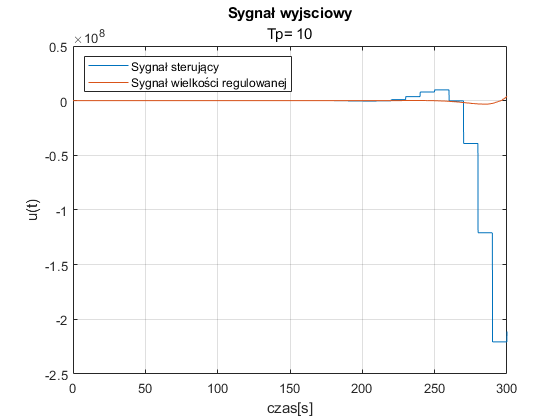

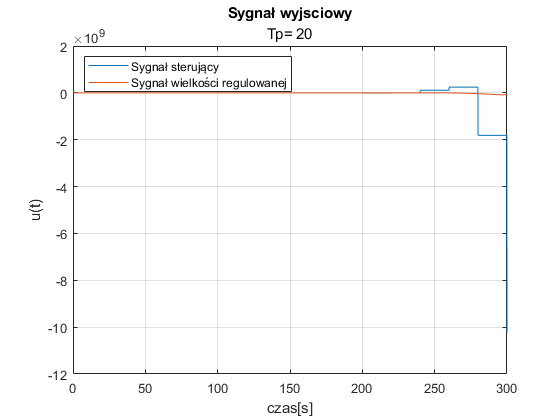

kr = 1.5;
Ti=45;
Td=11;

for Tp= [1 5 10 20]
    figure;
    out = sim('Zad3.slx');
    u = out.u;
    l = append("Tp= ", string(Tp));
    plot(u.time,u.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    legend("Sygnał sterujący","Sygnał wielkości regulowanej","Location","northwest");
    title("Sygnał wyjsciowy", l)
end